We will be analyzing the circuit below using nodal analysis

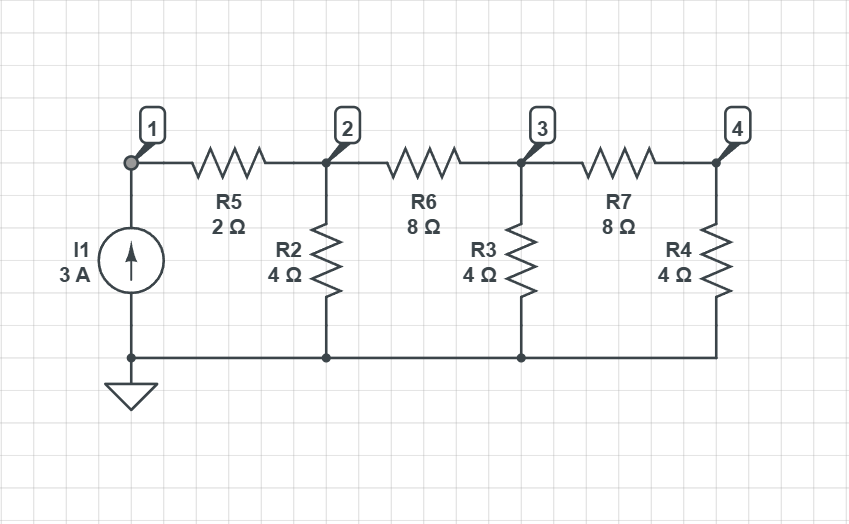

The incidence matrix is:

A= sym([-1 0 0 0 1 0 0; 0 -1 0 0 -1 1 0; 0 0 -1 0 0 -1 1; 0 0 0 -1 0 0 -1])

$$A = \left(\begin{array}{ccccccc} -1 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & -1 & 0 & 0 & -1 & 1 & 0\\ 0 & 0 & -1 & 0 & 0 & -1 & 1\\ 0 & 0 & 0 & -1 & 0 & 0 & -1 \end{array}\right)$$

And the matrix of the currents would look something like this:

syms i_1 i_2 i_3 i_4 i_5 i_6 i_7
i=[i_1; i_2; i_3; i_4; i_5; i_6; i_7; ]

$$i = \left(\begin{array}{c} i_{1}\\ i_{2}\\ i_{3}\\ i_{4}\\ i_{5}\\ i_{6}\\ i_{7} \end{array}\right)$$

Since Ai=0 

result = A * i;
eq = result == 0;
disp(eq)

$$\left(\begin{array}{c} i_{5}-i_{1}=0\\ i_{6}-i_{5}-i_{2}=0\\ i_{7}-i_{6}-i_{3}=0\\ -i_{4}-i_{7}=0 \end{array}\right)$$

We know that $i_1 =3$, and for $i_2,\; i_3,\; i_4,\; i_5,\; i_6$ and $i_7$ we can use Ohms law for closed circuits, after substituting these values we get:

syms u_2 u_3 u_4 u_5 u_6 u_7
syms R_2 R_3 R_4 R_5 R_6 R_7
subs_list = [i_1, i_2, i_3, i_4, i_5, i_6, i_7];
repl_list = [3,   u_2/R_2, u_3/R_3, u_4/R_4, u_5/R_5, u_6/R_6, u_7/R_7];
eq_substituted = subs(eq, subs_list, repl_list);
disp(eq_substituted)

$$\left(\begin{array}{c} \frac{u_{5}}{R_{5}}-3=0\\ \frac{u_{6}}{R_{6}}-\frac{u_{5}}{R_{5}}-\frac{u_{2}}{R_{2}}=0\\ \frac{u_{7}}{R_{7}}-\frac{u_{6}}{R_{6}}-\frac{u_{3}}{R_{3}}=0\\ -\frac{u_{4}}{R_{4}}-\frac{u_{7}}{R_{7}}=0 \end{array}\right)$$